# Test file

Bernardo Andrade Ortega

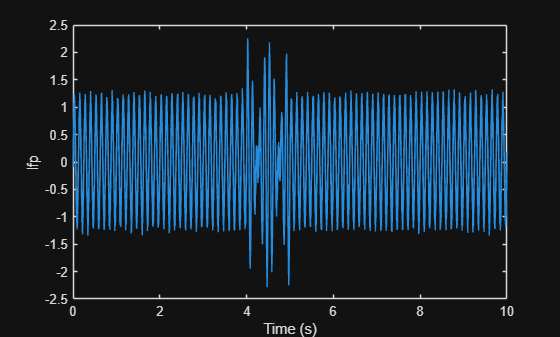

fs = 10000;
tv = 0:1/fs:10;

f1 = 8;
lfp = sin(tv .* f1 * (2 * pi)) + 0.1 * randn(1, length(tv));

tw = tv > 4 & tv < 5;
f2 = 10;
lfp(tw) = lfp(tw) + sin(tv(tw) .* f2 * (2*pi));

theta_band = [5,12];
TW = 3;

plot(tv,lfp)
xlabel('Time (s)')
ylabel('lfp')

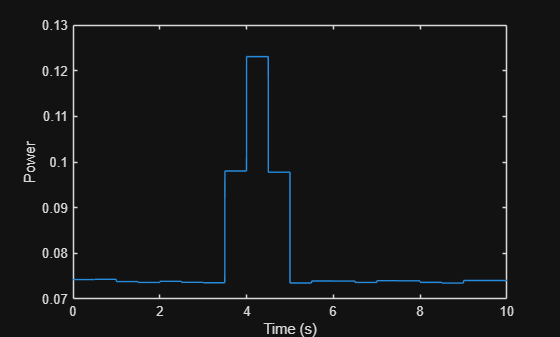

win = 1;
step = 0.5;
[power, t] = multitaper_power(lfp, fs, theta_band, TW, win, step);

plot(t, power)
xlabel('Time (s)')
ylabel('Power')

theta = bandpass(lfp, theta_band,fs);
theta_pow = abs(hilbert(theta)).^2;
round(win*fs)

ans = 10000

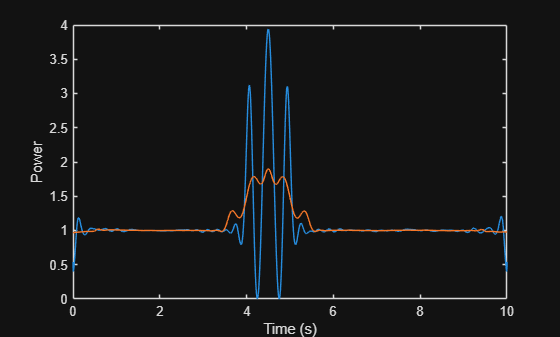

theta_pow_sm = movmean(theta_pow, round(win*fs));
plot(t, theta_pow)
hold on
plot(t, theta_pow_sm)
xlabel('Time (s)')
ylabel('Power')

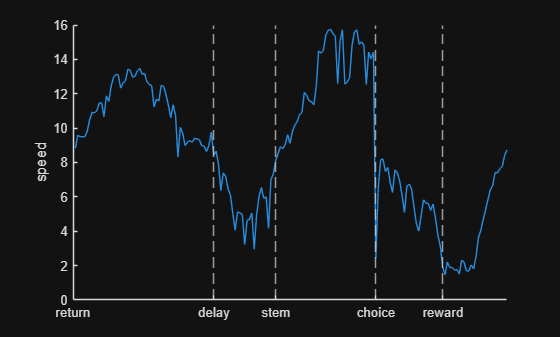

function linear_grid = fig8_linear(grid, name)
    armx_left = 1;
    armx_center = 23;
    armx_right = 45;
    y_top = 1;
    y_bottom = 70;
    returny_start = 35;
    x_ticks = [0, 59, 85, 127, 155];
    x_labels = ["return", "delay", "stem", "choice", "reward"];
    linear_grid = [];
    
    % Return
    linear_grid = [linear_grid, mean([grid(returny_start:y_bottom-1, armx_left) ...
                                      grid(returny_start:y_bottom-1, armx_right)]')];
    linear_grid = [linear_grid, mean([grid(y_bottom-1, armx_left+1) ...
                                      grid(y_bottom-1, armx_right-1)])];
    linear_grid = [linear_grid, mean([grid(y_bottom, armx_left+1:armx_center); ...
                                      grid(y_bottom, flip(armx_center:armx_right-1))])];
    
    % Center arm
    linear_grid = [linear_grid, grid(flip(y_top+1:y_bottom-1), armx_center)'];
    
    % Top arm
    linear_grid = [linear_grid, mean([grid(y_top, armx_center:armx_right-1); ...
                                      grid(y_top, flip(armx_left+1:armx_center))])];
    
    % Reward
    linear_grid = [linear_grid, mean([grid(y_top+1, armx_left+1) ...
                                      grid(y_top+1, armx_right-1)])];
    linear_grid = [linear_grid, mean([grid(y_top+1:returny_start-1, armx_left) ...
                                      grid(y_top+1:returny_start-1, armx_right)]')];
    
    % Plot
    plot(linear_grid)
    xline(x_ticks, LineStyle="--")
    ylabel(name)
    xlim([0,length(linear_grid)])
    xticks(x_ticks)
    xticklabels(x_labels)
    box off
end


linear_grid = fig8_linear(vel_grid, "speed");

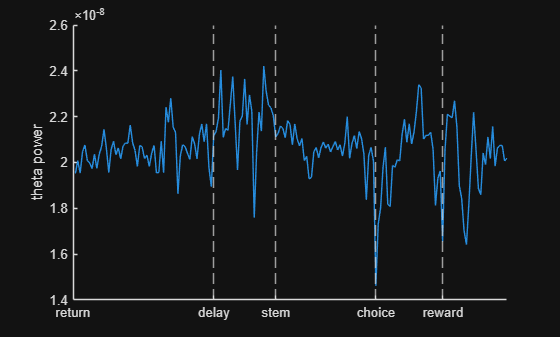

linear_grid = fig8_linear(power_grid, "theta power");

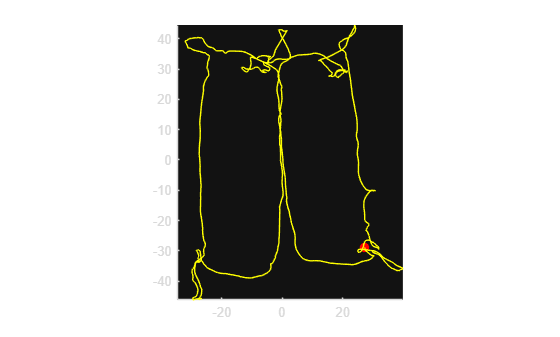

clf
makeTrajectoryVideo(praw.x, praw.y, praw.t, 5, "position_test.mp4")

x_bound = 10

x_bound = 10

tran = get_transitions(praw.x, praw.y,x_bound,100);
ind = tran(1,:);


tran =          554        1069        1587        1896        2422        2926        3506        3914        4288        5061
          -1           1           1          -1           1          -1           1          -1           1          -1
           1           1           0           1           1           1           1           1           1           1


ans = 9

ans = 1

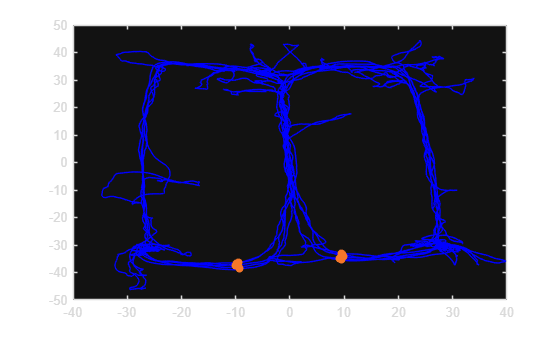

clf, hold off
plot(praw.x, praw.y, color="blue")
hold on
scatter(praw.x(ind), praw.y(ind), "filled",ColorVariable=tran(2,:))

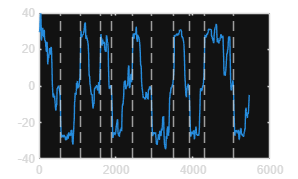

clf, hold off

plot(praw.x)
xline(ind,LineStyle="--")

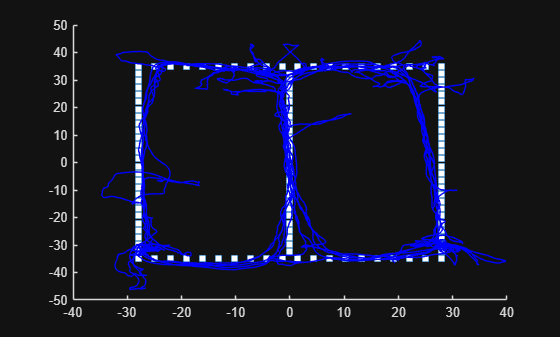

range = [-28, 28; -35, 35];
n_bin = [20, 28];
std_grid = make_std_grid(range,n_bin);

clf
scatter(std_grid(1,:), std_grid(2,:), 's', 'MarkerFaceColor', 'white')
hold on
plot(praw.x, praw.y, color="blue")
hold off

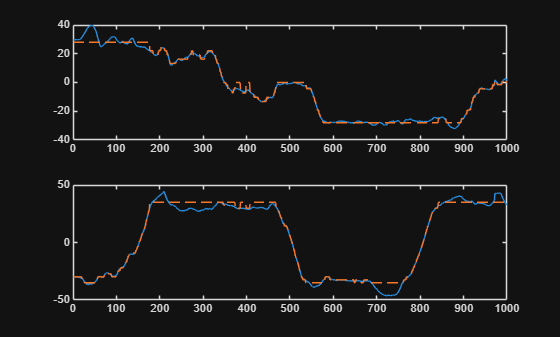

pos = [praw.x, praw.y].';
d_lim = 10;
p_ideal = get_p_ideal(pos, std_grid, d_lim);

r = 1:1000; %r = r + 1000; %
clf
subplot(2,1,1)
plot(pos(1,r))
hold on
plot(p_ideal(1,r),LineStyle="--")
hold off
subplot(2,1,2)
plot(pos(2,r))
hold on
plot(p_ideal(2,r),LineStyle="--")
hold off

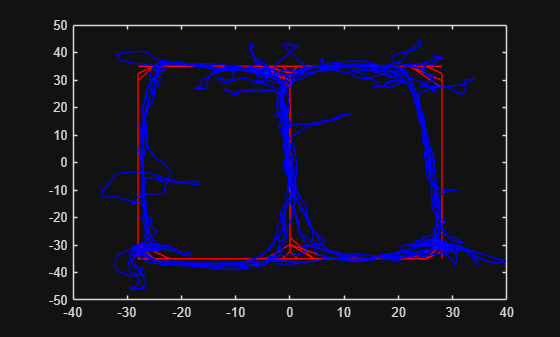

clf
plot(p_ideal(1,:), p_ideal(2,:), "Color","red")
hold on
plot(pos(1,:), pos(2,:), color="blue")
hold off

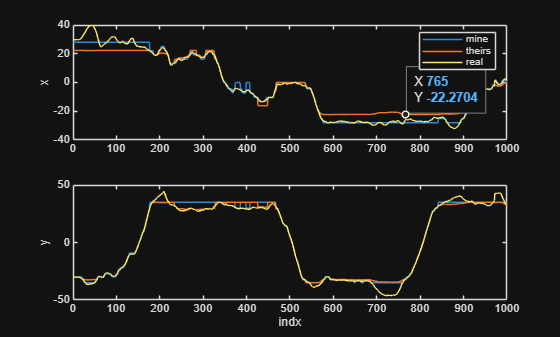

n = 1000;
clf
subplot(2,1,1)
plot(p_ideal(1,1:n))
hold on
plot(pideal.x(1:n))
plot(praw.x(1:n))
ylabel("x")
legend("mine","theirs","real")
hold off
subplot(2,1,2)
plot(p_ideal(2,1:n))
hold on
plot(pideal.y(1:n))
plot(praw.y(1:n))
ylabel("y")
xlabel("indx")
hold off

function p_ideal = get_p_ideal(pos, std_grid, d_lim)
    % pos : [x; y]
    % std_grid : [x; y]
    n_points = size(pos,2);
    p_ideal = zeros(2,n_points);

    idx = knnsearch(std_grid.', pos(:,1).');
    p_ideal(:,1) = std_grid(:, idx);

    for t = 2:n_points
        d = sqrt(sum((std_grid - p_ideal(:,t-1)).^2, 1));
        close_p = std_grid(:,d < d_lim);

        idx = knnsearch(close_p.', pos(:,t).');
        p_ideal(:,t) = close_p(:, idx);
    end
end

function std_grid = make_std_grid(range, n_bin)
    % range : [x_min,x_max; y_min,y_max]
    % n_bin : [n_x, n_y]

    x_hor = linspace(range(1,1), range(1,2), n_bin(1));
    y_hor = zeros(1, n_bin(1));

    x_ver = zeros(1, n_bin(2));
    y_ver = linspace(range(2,1), range(2,2), n_bin(2));

    up_arm = [x_hor; y_hor + range(2,2)];
    down_arm = [x_hor; y_hor + range(2,1)];

    left_arm = [x_ver + range(1,1); y_ver];
    center_arm = [x_ver; y_ver];
    right_arm = [x_ver + range(1,2); y_ver];
    
    std_grid = [up_arm, left_arm(:,2:end-1), left_arm(:,2:end-1), ...
        center_arm(:,2:end-1), right_arm(:,2:end-1), down_arm];
end

function tran = get_transitions(x,y,x_bound,win)
    % x, y : position
    % t    : time vector (same length)
    % tw   : time window (seconds)
    tran_ind = [];
    tran_typ = [];
    hits = 1;
    for t = 1:length(x)
        if y(t) < 0 && abs(x(t)) < x_bound && all(abs(x(t+1:t+win)) > x_bound)

            tran_ind = [tran_ind, t];
            tran_typ = [tran_typ, sign(x(t))];

            if length(tran_ind) > 1
                hit =  abs(sign(tran_typ(end)) - sign(tran_typ(end-1))) / 2;
                hits = [hits, hit];
            end

        end
    end
    tran = [tran_ind; tran_typ; hits];
end

           

function makeTrajectoryVideo(x, y, t, tw, filename)

% x, y : position
% t    : time vector (same length)
% tw   : time window (seconds)
% filename : output video file

% --- parameters ---
fps = 100;
pointSize = 50;

% --- video ---
v = VideoWriter(filename, 'MPEG-4');
v.FrameRate = fps;
open(v)

%figure('Color','w');
axis equal
xlim([min(x) max(x)])
ylim([min(y) max(y)])
hold on

% pre-create objects (FAST)
hPoint = scatter(NaN, NaN, pointSize, 'r', 'filled');

for i = 1:length(t)

    % --- time window selection ---
    t_now = t(i);
    idx = t >= (t_now - tw) & t <= t_now;

    xt = x(idx);
    yt = y(idx);

    plot(xt,yt,color="yellow")

    % --- current point ---
    set(hPoint, 'XData', x(i), 'YData', y(i))

    drawnow

    % --- write frame ---
    frame = getframe(gcf);
    writeVideo(v, frame);
end

close(v)
end

function [power, t] = multitaper_power(lfp, fs, freq_band, TW, win, step)
    % Calculates multitaper power for a frequency band using pmtm
    % Power is computed every "step" seconds and repeated to match input length
    %
    % Inputs:
    %   lfp        : 1D array (T samples)
    %   fs         : sampling rate (Hz)
    %   freq_band  : [f_start f_end] (Hz)
    %   TW         : time-bandwidth product
    %   K          : number of tapers
    %   win        : window size (seconds)
    %   step       : step size (seconds)
    %
    % Outputs:
    %   power      : multitaper band power, size(lfp)
    %   t          : time vector (seconds)
    
    lfp = lfp(:); 
    T = length(lfp);
    t = (0:T-1)' / fs;
    
    win_samp = round(win  * fs);
    step_samp = round(step * fs);
    
    power = nan(T,1);
    
    idx = 1;
    while idx + win_samp - 1 <= T
    
        seg = lfp(idx : idx + win_samp - 1);
    
        % Multitaper PSD
        [Pxx, f] = pmtm(seg, TW, [], fs);
    
        % Frequency band mask
        band_mask = (f >= freq_band(1)) & (f <= freq_band(2));
    
        % Mean band power
        band_power = mean(Pxx(band_mask));
    
        % Assign power to step-sized region
        assign_end = min(idx + step_samp - 1, T);
        power(idx:assign_end) = band_power;
    
        idx = idx + step_samp;
    end
    
    % trailing NaNs with last valid value
    last_valid = find(~isnan(power), 1, 'last');
    if ~isempty(last_valid)
        power(last_valid:end) = power(last_valid);
    end
end